# Example 6.20: 2D Signals as Superposition of 2D Waves

Note: this script reproduces Example 6.20 (Section 6.3.5) of **Statistics for Chemical Engineers**: a 2D signal built from a low-frequency and a high-frequency wave. Victor Z UW-Madison, 2020 Fourier transform in 2D

clc; clear all; close all hidden

## Waves

create 2D periodic signals

x=linspace(0,10,100);
y=linspace(0,10,100);
[X,Y]=meshgrid(x,y);

% color space
c=linspace(0.99,0.0,100)';
C=[c,c,c];

% create low freq signal
om1=10;
f1=sin(2*pi*om1*(X+Y));

subplot(3,2,3)
s=surf(f1)

s =   Surface with properties:

       EdgeColor: [0.1294 0.1294 0.1294]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×100 double)
           YData: [100×1 double]
           ZData: [100×100 double]
           CData: [100×100 double]

  Show all properties

set(gca,'YTickLabel',[]);
set(gca,'XTickLabel',[]);
set(gca,'ZTickLabel',[]);
direction = [1 0 1];
rotate(s,direction,10)
ylabel('$x_2$','Interpreter','Latex','FontSize',14)
xlabel('$x_1$','Interpreter','Latex','FontSize',14)
zlabel('$f_1(x_1,x_2)$','Interpreter','Latex','FontSize',14)

subplot(3,2,4)
imagesc(f1)
colormap(C);
set(gca,'YTickLabel',[]);
set(gca,'XTickLabel',[]);
set(gca,'ZTickLabel',[]);
ylabel('$x_2$','Interpreter','Latex','FontSize',14)
xlabel('$x_1$','Interpreter','Latex','FontSize',14)

% create high freq signal
om2=60;
f2=sin(2*pi*om2*(X+Y));

subplot(3,2,5)
s=surf(f2)

s =   Surface with properties:

       EdgeColor: [0.1294 0.1294 0.1294]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×100 double)
           YData: [100×1 double]
           ZData: [100×100 double]
           CData: [100×100 double]

  Show all properties

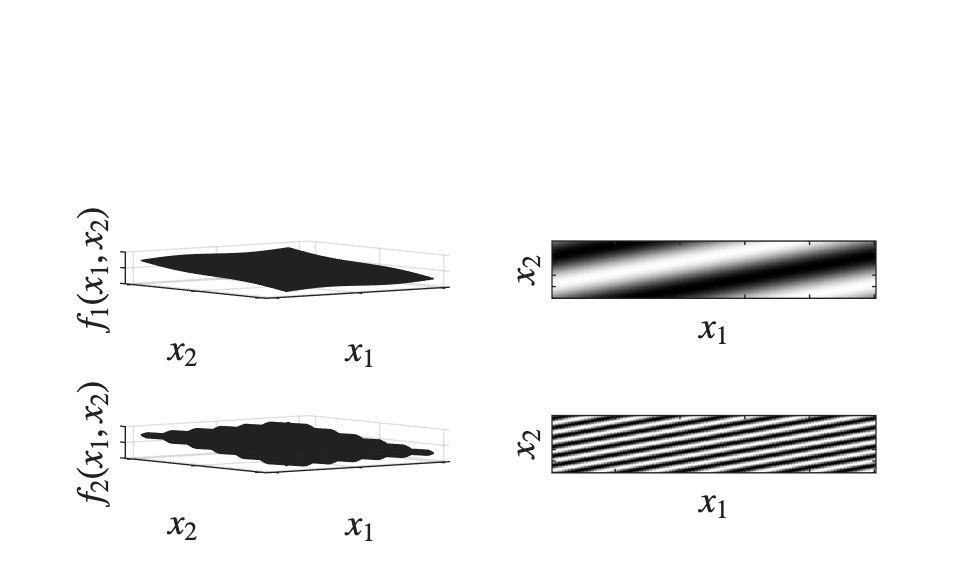

set(gca,'YTickLabel',[]);
set(gca,'XTickLabel',[]);
set(gca,'ZTickLabel',[]);
ylabel('$x_2$','Interpreter','Latex','FontSize',14)
xlabel('$x_1$','Interpreter','Latex','FontSize',14)
zlabel('$f_2(x_1,x_2)$','Interpreter','Latex','FontSize',14)
direction = [1 0 1];
rotate(s,direction,10)

subplot(3,2,6)
imagesc(f2)
colormap(C);
set(gca,'YTickLabel',[]);
set(gca,'XTickLabel',[]);
set(gca,'ZTickLabel',[]);
ylabel('$x_2$','Interpreter','Latex','FontSize',14)
xlabel('$x_1$','Interpreter','Latex','FontSize',14)

## Total signal

total signal

f=f1+f2;
subplot(3,2,1)
s=surf(f)

s =   Surface with properties:

       EdgeColor: [0.1294 0.1294 0.1294]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×100 double)
           YData: [100×1 double]
           ZData: [100×100 double]
           CData: [100×100 double]

  Show all properties

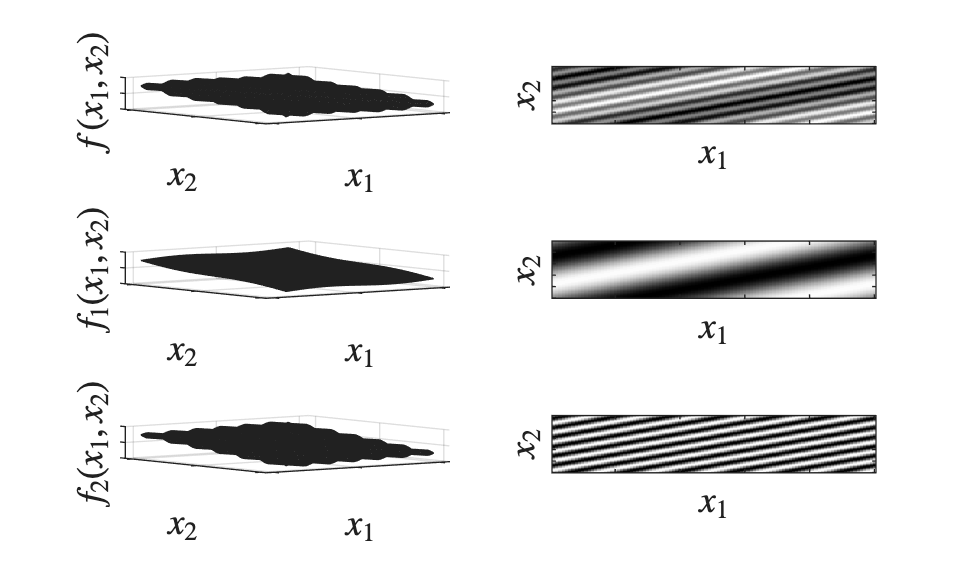

set(gca,'YTickLabel',[]);
set(gca,'XTickLabel',[]);
set(gca,'ZTickLabel',[]);
direction = [1 0 1];
rotate(s,direction,10)
ylabel('$x_2$','Interpreter','Latex','FontSize',14)
xlabel('$x_1$','Interpreter','Latex','FontSize',14)
zlabel('$f(x_1,x_2)$','Interpreter','Latex','FontSize',14)
subplot(3,2,2)
imagesc(f)
colormap(C);
set(gca,'YTickLabel',[]);
set(gca,'XTickLabel',[]);
set(gca,'ZTickLabel',[]);
ylabel('$x_2$','Interpreter','Latex','FontSize',14)
xlabel('$x_1$','Interpreter','Latex','FontSize',14)

print -depsc -r1200 ch6_2dsinetotal.eps

## Note

As in the book, any image is a superposition of waves of different frequencies; identifying them lets us design filters.